# Analyzing Electrocardiogram Data

This example shows how to do a simple analysis of an electrocardiogram (ECG) signal. The signal is a measure of electrical activity of the heart over time.

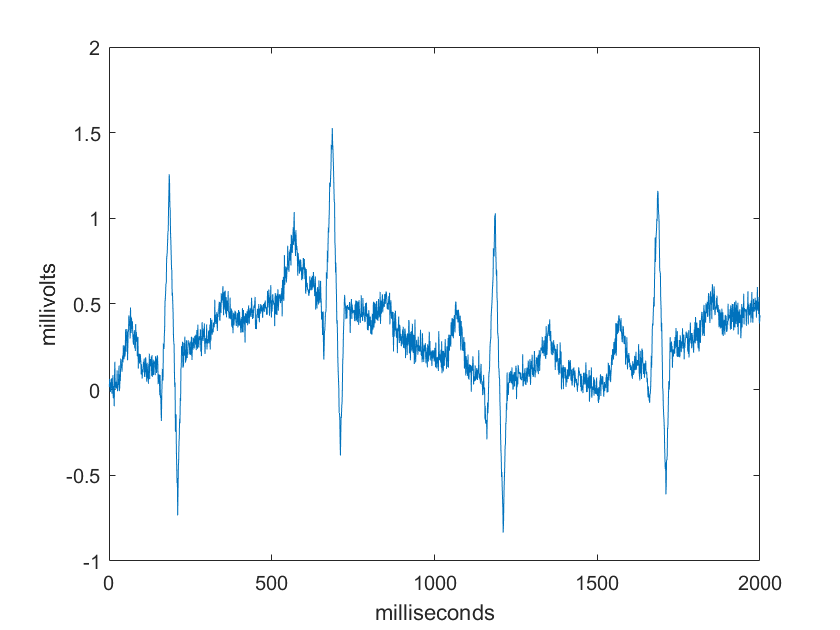

load noisyecg
plot(noisyECG)
xlabel('milliseconds')
ylabel('millivolts')

## Remove Trends in the Data

The signal is measured by electrodes attached to the skin and is sensitive to disturbances such as power source interference and noises due to movement.  The above signal shows a baseline shift and therefore does not represent the true amplitude. We can use the **Remove Trends **task to fit the baseline shift to a polynomial and remove it.

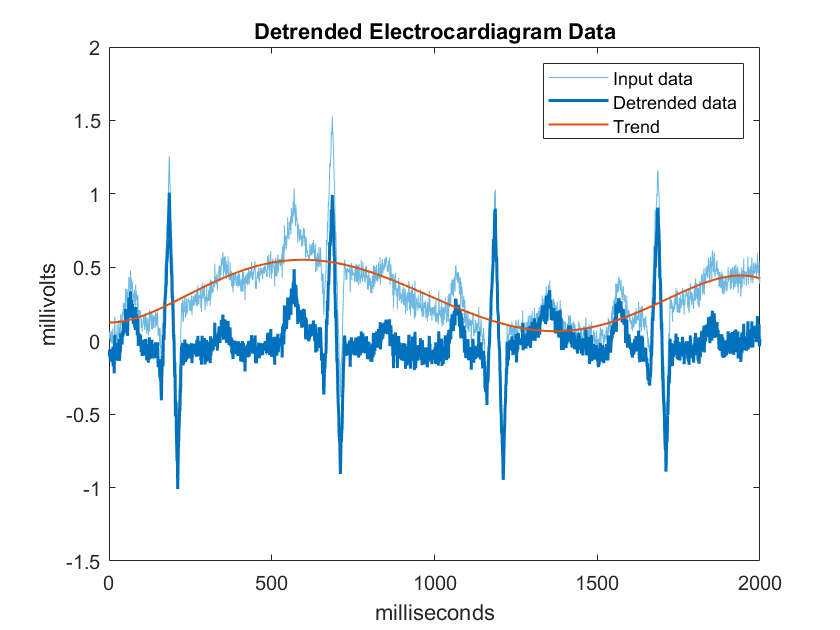

% Remove trend from data
detrendedECGData = detrend(noisyECG,5);

% Display results
clf
plot(noisyECG,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(detrendedECGData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(noisyECG-detrendedECGData,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend
xlabel('milliseconds')
ylabel('millivolts')

title('Detrended Electrocardiagram Data')

## Find the R Wave Maximums

In an elecrocardiogram, the R wave it the large upward deflection in the signal that represents the deploarization of the main mass of the heart's ventricles.  The R-waves can be detected by thresholding peaks above 0.5mV.  We can use the Find Local Extrema task

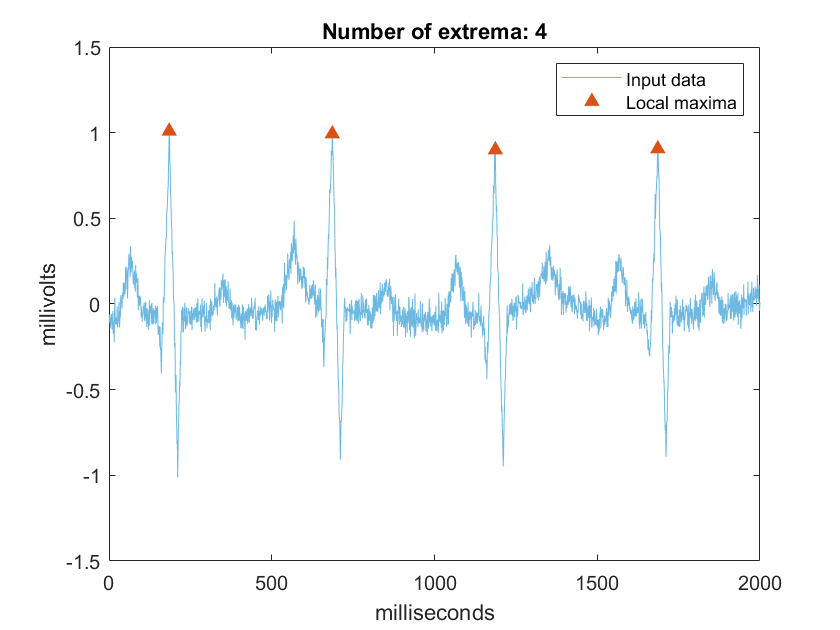

% Find local maxima
maxIndices = islocalmax(detrendedECGData,'MaxNumExtrema',4);

% Display results
clf
plot(detrendedECGData,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(find(maxIndices),detrendedECGData(maxIndices),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices))])
hold off
legend
xlabel('milliseconds')
ylabel('millivolts')

## Calculate the Heart Rate

We can now calculate the heart rate from the time interval between R wave maximums.

maxValues = find(maxIndices);
timePerBeat = sum((maxValues(2:4) - maxValues(1:3)))/3;
% Calculate heart rate